# Thermoeconomic Diagnosis Demo

Use ThermoeconomicDiagnosis function to compare two states of the plant ans make diagnosis

#### Select and check the model file

file='tgas_model.xlsx';
model=CheckDataModel(file);

INFO: cStatusLogger. Productive Structure is valid
INFO: cStatusLogger. Format Configuration is valid
INFO: cStatusLogger. Exergy values [Reference] are valid
INFO: cStatusLogger. Exergy values [TURB86] are valid
INFO: cStatusLogger. Exergy values [COMP86] are valid
INFO: cStatusLogger. Exergy values [PC78] are valid
INFO: cStatusLogger. Exergy values [T25] are valid
INFO: cStatusLogger. Exergy values [ECTR] are valid
INFO: cStatusLogger. Resources Cost sample [Base] is valid
INFO: cStatusLogger. Resources Cost sample [STACK] is valid
INFO: cStatusLogger. Waste definition is valid
INFO: cReadModelXLS. Data Model tgas_model.xlsx is valid


#### Select the parameters

States=convertCharsToStrings(model.getStateNames);
State=convertStringsToChars(States(4));
DiagnosisMethod='WASTE_OUTPUT';

#### Compute Cost Analysis

res=ThermoeconomicDiagnosis(model,'State',State,'DiagnosisMethod',DiagnosisMethod);

#### Show Results

res.fuelImpact;

Fuel Impact:   294.000 (kW)


printResults(res);

Diagnosis Sumary

  Id  Key       MF(kW)     DI(kW)    DPs(kW)    MF*(kW)    MR*(kW)   DPs*(kW)
------------------------------------------------------------------------------
   1  COMB      53.447    140.000      0.000     53.447      0.000      0.000
   2  COMP      -0.766      5.000      0.000     -1.329      0.000      0.000
   3  GTRB      -2.280      2.000      0.000     -1.739      0.000      0.000
   4  HRSG      68.800     68.800      0.000    114.534      0.000      0.000
   5  STCK       0.000      0.000     78.200      0.079      0.000    129.008
   6  ENV      119.201    215.800     78.200    164.992      0.000    129.008


 Malfunction Table (kW)

             COMB      COMP      GTRB      HRSG      STCK       DPs
--------------------------------------------------------------------
 COMB       0.000     0.000    -8.282    45.539    -0.261     0.000
 COMP       0.000     0.000     6.002    23.261     0.261     0.000
 GTRB       0.000    -0.766     0.000     0.000     0.000

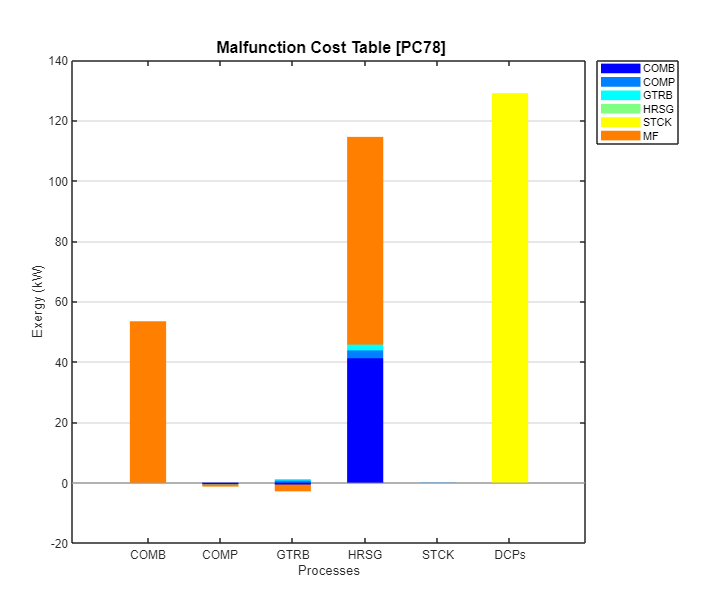

graphDiagnosis(res);